# Common Cold Scenario

*Author:* Zachary del Rosario, Fall 2020

*Purpose:* Generate data with a known ground-truth for students to fit a model against.

## Generate Data

Generate data under a ground-truth setting.

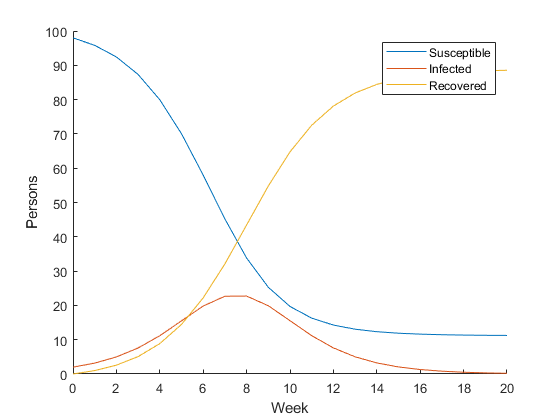

% Define parameters
beta = 1 / 90; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / day)
% Set up system
tab_state = fcn_make_table( ...
    "s", 98, ...
    "i", 2, ...
    "r", 0 ...
);
tab_system = fcn_make_table("beta", beta, "gamma", gamma);

% Run simulation
tab_record = fcn_simulate(tab_state, tab_system, 20);

% Plot
figure(1); clf; hold on;
plot(tab_record.week, tab_record.s); label1 = "Susceptible";
plot(tab_record.week, tab_record.i); label2 = "Infected";
plot(tab_record.week, tab_record.r); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})

Check a summary of the simulation.

describe(tab_record)

ans = 6×5 table
      s         i         r       week       stat  
    ______    ______    ______    _____    ________

        98    22.727    88.557       20    "Max"   
    72.524    15.512    86.307    15.25    "Q3"    
    39.542    8.4436    52.015       10    "Mean"  
    19.691    5.0105    64.765       10    "Median"
    11.823    1.8254    13.058     4.75    "Q1"    
    11.242    0.2011         0        0    "Min"   


We'll use this model as the ground-truth for a student exercise.

## Mask the Data

Mask the data on a detection threshold

% Set a lower detection threshold
min_i = 1;
max_week = 6;
% Filter the data based on threshold
tab_tmp = tab_record((tab_record.i >= min_i) & (tab_record.week <= max_week), :);
tab_data = apply(@round, tab_tmp)

tab_data = 7×4 table
    s     i     r     week
    __    __    __    ____

    98     2     0     0  
    96     3     1     1  
    92     5     3     2  
    87     8     5     3  
    80    11     9     4  
    70    16    14     5  
    58    20    22     6  


Write the data to a csv.

writetable(tab_data(:, ["i", "week"]), "infected.csv")